# Visualize Geographic Information using a Bubble Chart  

`geobubble` creates a geographic bubble chart with filled circles (bubbles) of varying size to information about geographic locations specified in a table displayed on a map

### Import Global Tsunami Data

Read historic tsunami data into the workspace as a table. The rows represent individual tsunami occurrences, the columns represent data about a set of variables for each tsunami, such as its location (latitude and longitude), cause, and maximum height of the tsunami wave.

tsunamis = readtable("tsunamis.xlsx");

### Basic Geobubble Plot

Plot the tsunami data defined by latitude-longitude pairs corresponding to the maximum wave height at that point. The Generated plot fits a globe image to the included points and draws sizes based on the data magnitude.

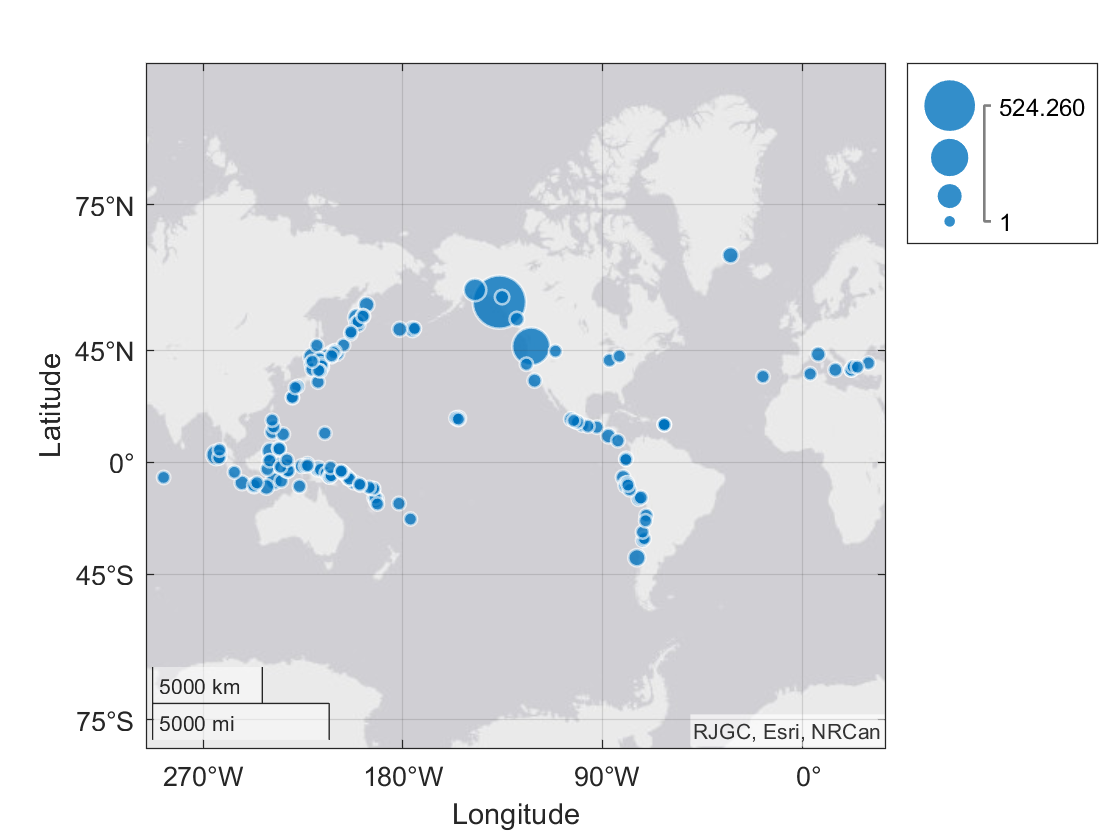

geobubble(tsunamis.Latitude,tsunamis.Longitude,tsunamis.MaxHeight);

## Customize Colors Based on Categories 

Turn one of the table variables into a categorical variable to specify the color of the bubbles. The `Cause` variable attributes a cause to each tsunami, such as, `'Earthquake'`, `'Volcano'`, or `'Earthquake and Landslide'`. Convert the `Cause` variable from a cell array of character vectors into a categorical variable.

colordata = categorical(tsunamis.Cause);

Create a geographic bubble chart, plotting the locations of the tsunamis on a map. Use bubble size to indicate the size of the wave, and use bubble color to indicate the cause of the tsunami. Add a title and legend size using a name-value pair.

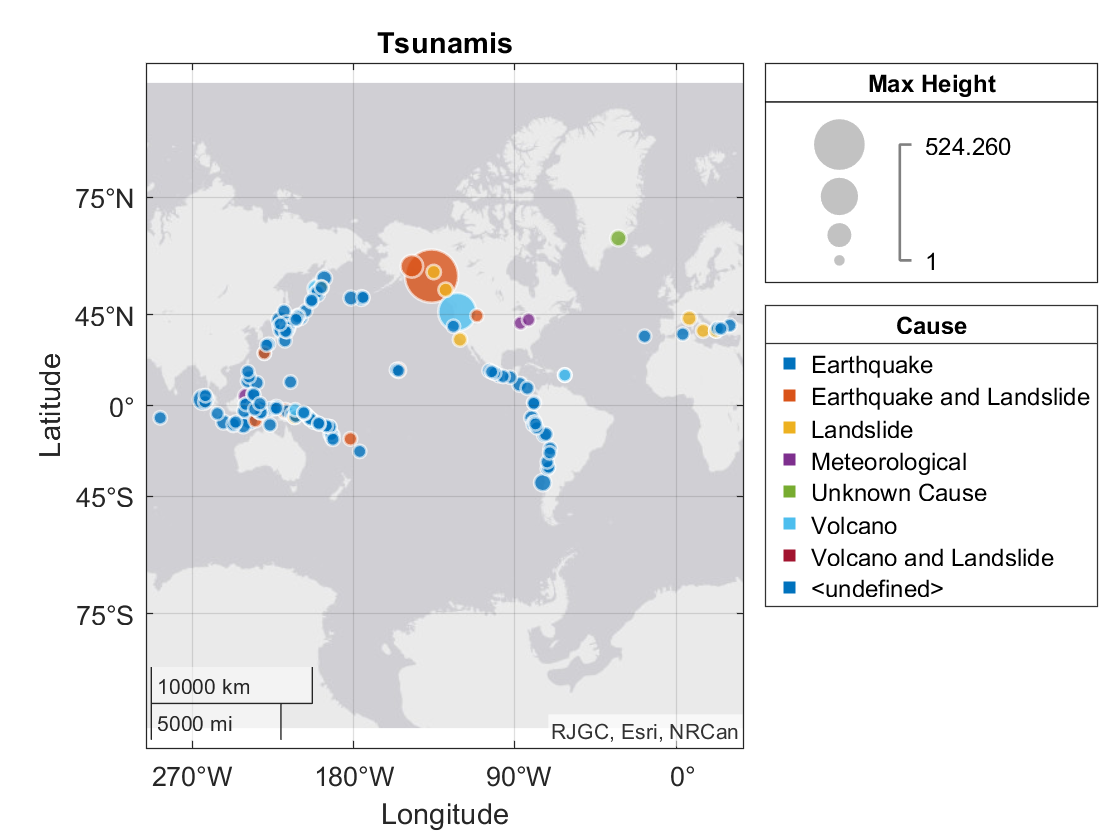

gb = geobubble(tsunamis.Latitude,tsunamis.Longitude,tsunamis.MaxHeight,...
    colordata,...                                                               % define color based on categorical variable
    "Title","Tsunamis",...                                                      % Add chart title                                               
    "SizeLegendTitle","Max Height",...                                          % Add legend for the bubble size
    "ColorLegendTitle","Cause");                                                % add color legend based on cause

## Additional Information

### Get All Geobubble Properties

Graphics objects in MATLAB have many properties. To see all the properties of a geobubble, uncomment the following code

% get(gb)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[geobubble](https://www.mathworks.com/help/matlab/ref/geobubble.html)